# Phase Coding Method

lena = imread('lena_std.tif');
lena_gray = rgb2gray(lena);

% encryted the image by key
key = 3;
lena_gray_en = encryption2D(lena_gray, key);

[LoD, HiD, LoR, HiR] = wfilters('haar');
[cA, cH, cV, cD] = dwt2(lena_gray_en, LoD, HiD, 'mode', 'symh');

lena_b = de2bi(uint16(cA))

lena_b = 65536×9 uint16 matrix
   1   0   1   0   0   0   1   1   0
   0   1   1   1   1   0   0   1   0
   0   1   0   1   1   1   0   1   0
   0   0   0   1   1   0   1   1   0
   1   1   0   1   1   0   0   0   1
   1   0   1   1   0   0   1   0   1
   1   0   1   1   1   0   1   1   0
   0   0   0   0   0   0   0   0   1
   1   1   0   1   0   1   1   1   0
   1   0   0   0   1   0   0   0   1


# Organize Embedding Data

[N, B] = size(lena_b);
lena_b = lena_b.';
lena_b = lena_b(:);

% Setting for Coding Data
num_seg = 100;
num_seg_data = floor(N*B/num_seg) + 1;
data = zeros(num_seg, num_seg_data);
t = 1;
for i = 1:num_seg
    for j = 1:num_seg_data
        if (t <= N*B)
            data(i,j) = lena_b(t);           
        else
            data(i,j) = 0;
        end
        t = t + 1;
    end    
end

# Segmented Audio Fourier Transform

[y,Fs] = audioread('audio.wav');

num_part = 5;
% Segmented Fourier Transform
len_seg = 3*num_seg_data;
if (mod(len_seg,2) == 1)
    len_seg = len_seg + 1;
end
Y = zeros(num_seg, num_part, len_seg);

for l = 1:num_seg
    for i = 1:num_part
        Y(l,i,:) = fft(y((l-1)*num_part*len_seg+len_seg*(i-1)+1 : (l-1)*num_part*len_seg+len_seg*i));
    end
end

% Extract phase & amplitude
phi = zeros(num_seg, num_part, len_seg);
amp = zeros(num_seg, num_part, len_seg);
for l = 1:num_seg
    for i = 1:num_part
        phi(l,i,:) = angle(Y(l,i,:));
        amp(l,i,:) = abs(Y(l,i,:));
    end    
end

delta = zeros(num_seg, num_part, len_seg);
for l = 1:num_seg
    for i = 1:num_part-1
        delta(l,i,:) = phi(l,i+1,:) - phi(l,i,:);
    end    
end

% Transform binary image data to phase representation
phi_d = zeros(num_seg,num_seg_data);
for l = 1:num_seg
    for i = 1:num_seg_data
        if (data(l,i) == 1)
            phi_d(l,i) = pi/2;
        else
            phi_d(l,i) = -pi/2;
        end
    end    
end

% Phase Coding Embedding
for l = 1:num_seg
    for i = 1:num_seg_data
        phi(l,1,len_seg/2+1+i) = -phi_d(l,num_seg_data+1-i);%phi(1,N/2+1+i)-phi_d(M+1-i);
        phi(l,1,len_seg/2-num_seg_data+i) = phi_d(l,i);%phi(1,N/2+1+i)+phi_d(i);
    end    
end

% Calculate new phase by adding the difference
for l = 1:num_seg
    for i = 1:num_part-1
        phi(l,i+1,:) = phi(l,i,:) + delta(l,i,:);
    end    
end

% Convert back to time domain signal
Y_p = zeros(num_seg, num_part, len_seg);
y_p = zeros(num_seg, num_part, len_seg);
for l = 1:num_seg
    for i = 1:num_part
        Y_p(l,i,:) = amp(l,i,:).*exp(1j*phi(l,i,:));
        y_p(l,i,:) = ifft(Y_p(l,i,:));   
    end
end

% Dimensional Reduction (3D -> 2D)
y_p_c = zeros(num_seg,num_part*len_seg);
tmp = zeros(num_part,len_seg);
for l = 1:num_seg
    tmp(:,:) = y_p(l,:,:);
    y_p_c(l,:) = reshape(tmp.',[],1);    
end

% Dimensional Reduction (2D -> 1D)
y_p_cc = reshape(y_p_c.',[],1);

% Encoded sound play
playerObj = audioplayer(real(y_p_cc), Fs);
play(playerObj);

stop(playerObj);

# Decoding

Y = zeros(num_seg,num_part,len_seg);
for l=1:num_seg
    for i=1:num_part
        Y(l,i,:) = fft(real(y_p_cc((l-1)*num_part*len_seg+len_seg*(i-1)+1 : (l-1)*num_part*len_seg+len_seg*i)));
    end
end
phi = zeros(num_seg, num_part, len_seg);
amp = zeros(num_seg, num_part, len_seg);
for l = 1:num_seg
    for i = 1:num_part
        phi(l,i,:) = angle(Y(l,i,:));
        amp(l,i,:) = abs(Y(l,i,:));
    end    
end

% Get the phase information
data = zeros(num_seg, num_seg_data);
for l = 1:num_seg
    for i = 1:num_seg_data
        data(l,i) = phi(l,1,len_seg/2-num_seg_data+i);
    end    
end

% pi/2 -> 1, -pi/2 -> 0
for l = 1:num_seg
    for i = 1:num_seg_data
        if (data(l,i) > 0)
            data(l,i) = 1;
        else
            data(l,i) = 0;
        end
    end    
end

% Convert data to binary image
B = 9;
N = 256*256;
lena_b_r = zeros(N*B,1);
t = 1;
for i = 1:num_seg
    for j = 1:num_seg_data
        if (t <= N*B)
            lena_b_r(t) = data(i,j);
        end
        t = t + 1;
    end    
end

% Reshape back to decimal value
lena_b_t = zeros(N, B);
t = 1;
for i = 1:N
    for j = 1:B
        lena_b_t(i, j) = lena_b_r(t, 1);
        t = t + 1;
    end
end
lena_recover_t = bi2de(lena_b_t);

% Convert back to 2D dimension
n = sqrt(N);
lena_gray_recover = zeros(n, n);
for i = 1:n
    for j = 1:n
        lena_gray_recover(i, j) = lena_recover_t(n*(j-1) + i);
    end
end
% lena_gray_recover = uint8(lena_gray_recover);

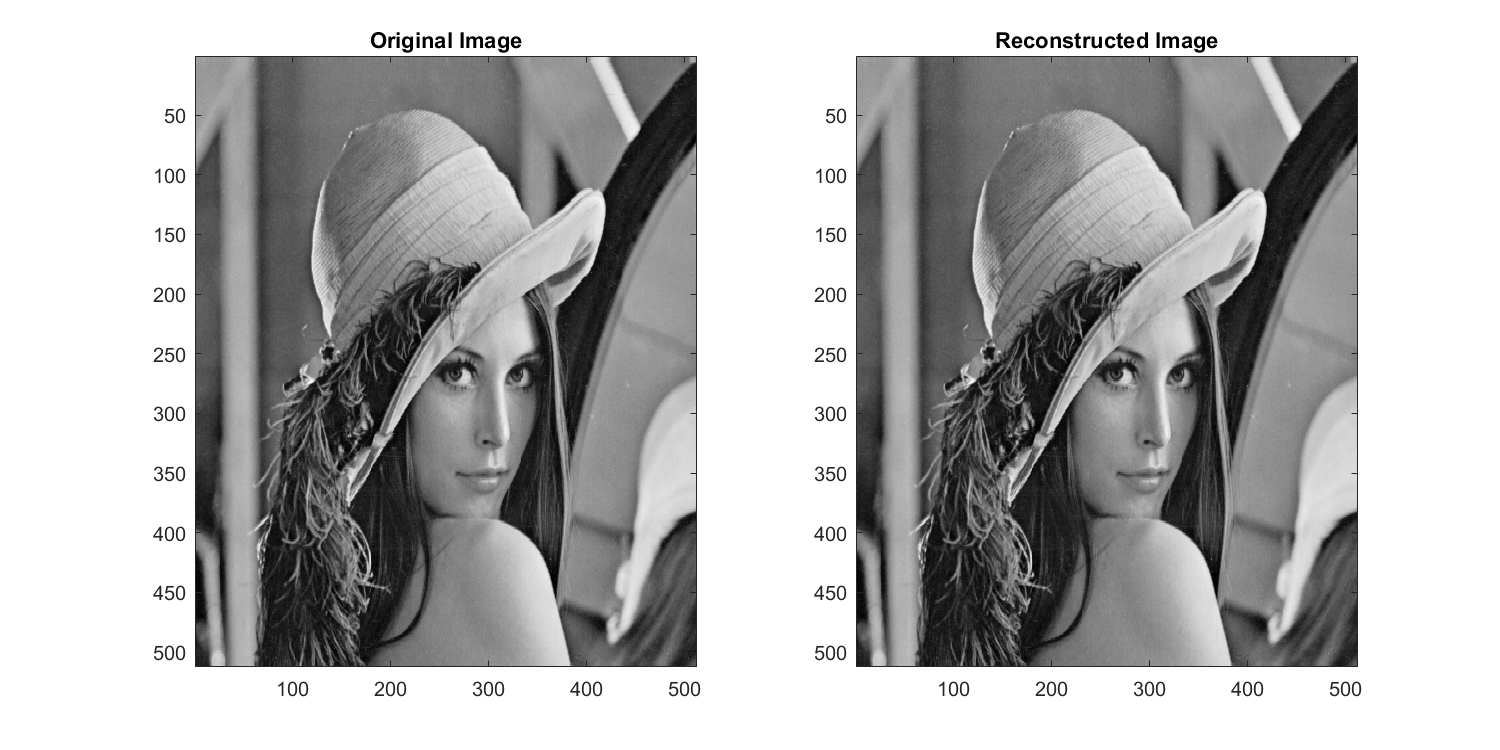

% decrypted using key
key = 3;
lena_img_re = idwt2(lena_gray_recover, cH, cV, cD, 'haar');
lena_img_de = decryption2D(lena_img_re, key);

% plotting
figure;
colormap('gray');
set(gcf, 'Position',  [100, 100, 1000, 500]);
subplot(1,2,1);
imagesc(lena_gray);
title('Original Image');
subplot(1,2,2);
imagesc(lena_img_de);
title('Reconstructed Image');

## Audio Checking

playerObj = audioplayer(real(y_p_cc),Fs);
play(playerObj);

stop(playerObj);

# Some qualitative results

Image

gen = lena_img_de/256;
ref = double(lena_gray)/256;

[peaksnr, snr] = psnr(gen, ref)

peaksnr = 63.1988

snr = 57.5081

mse = immse(gen, ref)

mse = 4.7876e-07

[ssimval, ssimmap] = ssim(gen, ref)

ssimval = 0.9999

ssimmap =     0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998
    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.999

Sound

[peaksnr, snr] = psnr(real(y_p_cc), y(1:num_seg*num_part*len_seg))

peaksnr = 60.3242

snr = 41.5323

mse = mean((real(y_p_cc)-y(1:num_seg*num_part*len_seg)).^2)

mse = 9.2808e-07